%Q2
h=0.1

h = 0.1000

domain = Domain('square');
mesh = Mesh(domain, h);

building mesh
- basic properties
- P1 basis
- stiffness and mass matrices
- differential matrices
done (308 triangles, 0.1 s)


P = mesh.nodes;
T = mesh.triangles;

M = matriceM(P, T);
K = matriceK(P, T);
fh = sin(pi*P(:,1)) .* sin(pi*P(:,2));

 
I = mesh.I_boundary_nodes;
nI = length(I);
K(I,:) = 0;
K(I,I) = speye(nI, nI);
B = M * fh;
B(I) = 0;
U = K \ B;

ans = 0.0341

%Q3
H = [0.025, 0.05, 0.075, 0.1];
errL2 = zeros(1, 4);
errH1 = zeros(1, 4);

for i = 1:4
    domain = Domain('square');
    mesh = Mesh(domain, H(i));
    P = mesh.nodes;
    T = mesh.triangles;

    M = matriceM(P, T);
    K = matriceK(P, T);

    NN = size(P, 1);
    fh = sin(pi*P(:,1)) .* sin(pi*P(:,2));

    % Calcul solution numérique
    I = mesh.I_boundary_nodes;
    nI = length(I);
    K(I,:) = 0;
    K(I,I) = speye(nI, nI);
    B = M * fh;
    B(I) = 0;
    U = K \ B;

    % Solution exacte et erreur
    u_exact = (1/(2*pi^2)) * sin(pi*P(:,1)) .* sin(pi*P(:,2));
    err = U - u_exact;

    errL2(i) = normL2(err, M);
    errH1(i) = normH1(err, M, K);
end

building mesh
- basic properties
- P1 basis
- stiffness and mass matrices
- differential matrices
done (5492 triangles, 0.4 s)
building mesh
- basic properties
- P1 basis
- stiffness and mass matrices
- differential matrices
done (1338 triangles, 0.1 s)
building mesh
- basic properties
- P1 basis
- stiffness and mass matrices
- differential matrices
done (596 triangles, 0.1 s)
building mesh
- basic properties
- P1 basis
- stiffness and mass matrices
- differential matrices
done (308 triangles, 0 s)


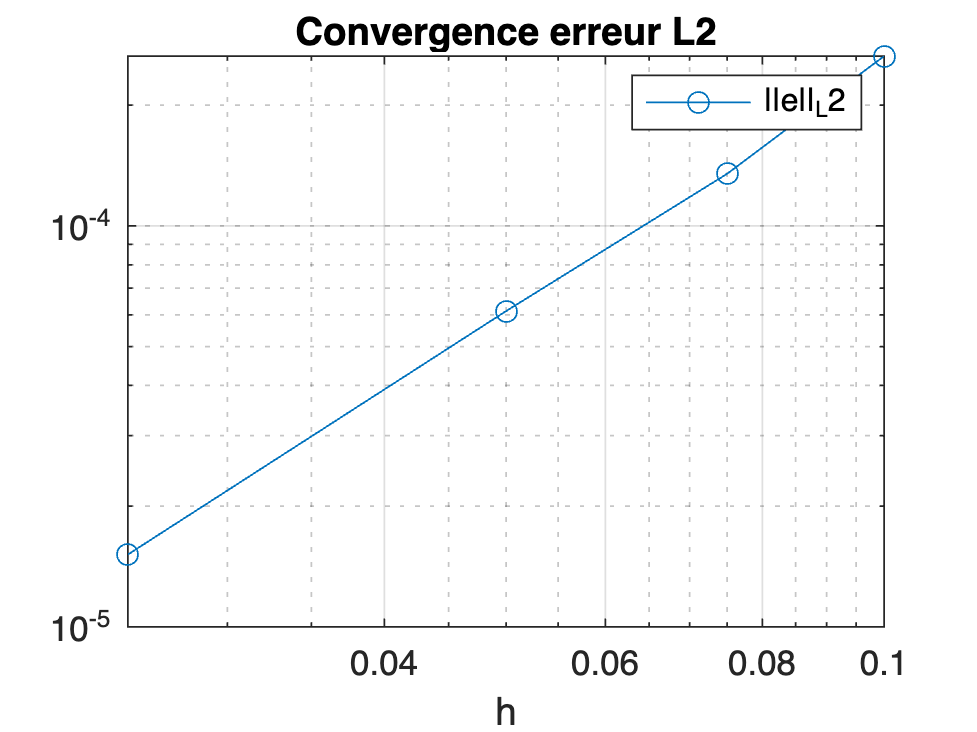


%2tude de la convergence
figure;
loglog(H, errL2, '-o', DisplayName='||e||_L2');
xlabel('h'); legend; grid on;
title('Convergence erreur L2');

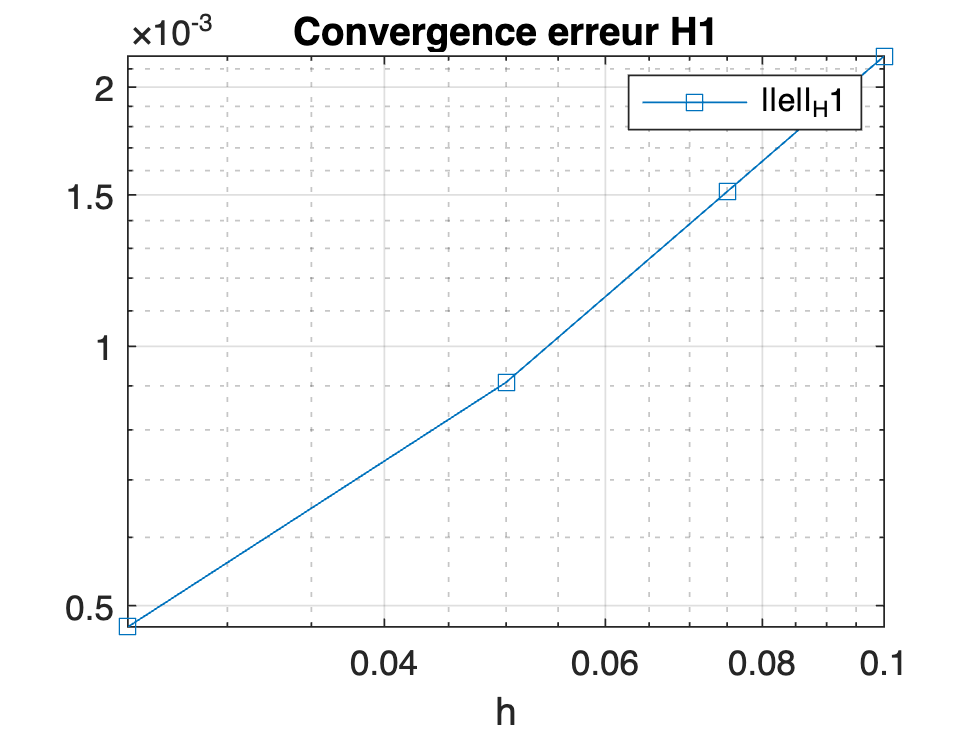


figure;
loglog(H, errH1, '-s', DisplayName='||e||_H1');
xlabel('h'); legend; grid on;
title('Convergence erreur H1');

%Ordre des convergence :

U =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


%Q4 - Maillage de mauvaise qualité
L = 5;
h=0.1;
domain_rec = Domain([0 0 ; 1 0 ; 1 L ; 0 L ]) ;
mesh_temp = Mesh( domain_rec , h * sqrt(L));

building mesh
- basic properties
- P1 basis
- stiffness and mass matrices
- differential matrices
done (326 triangles, 0.2 s)


mesh_bad = mesh_temp.move({0 ,@(x ,y) (1 - L)/L*y });

building mesh
- basic properties
- P1 basis
- stiffness and mass matrices
- differential matrices
done (308 triangles, 0 s)
- basic properties
- P1 basis
- stiffness and mass matrices
- differential matrices


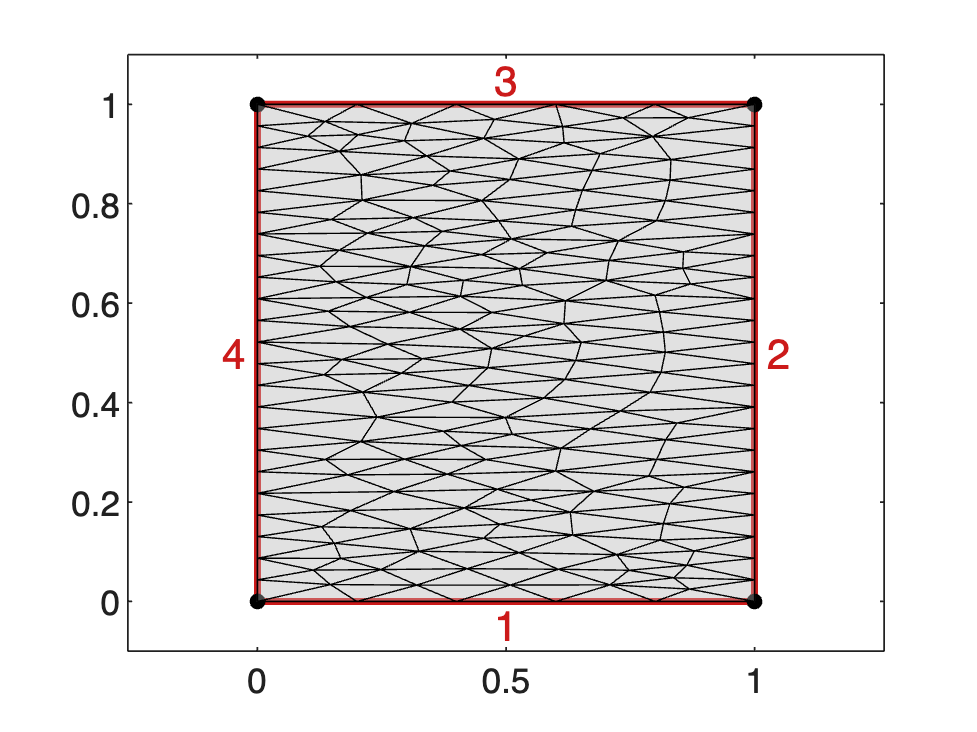

domain.plot('edgelabels');
hold on
mesh_bad.plot


P_bad=mesh_bad.nodes;
qual=1;
T_bad=mesh_bad.triangles;
for i = 1:size(T_bad,1)
    p1 = P_bad(T_bad(i,1), :);
    p2 = P_bad(T_bad(i,2), :);
    p3 = P_bad(T_bad(i,3), :);
    [s,d,q] = geo(p1,p2,p3);
    if q<qual
        qual=q;
    end
end
disp(qual)

    0.1138



%qualité=0.1138

%Q2&3 pour mesh_bad
H = [0.025, 0.05, 0.075, 0.1];
errL2 = zeros(1, 4);
errH1 = zeros(1, 4);
L=5;

for i = 1:4
    domain_rec = Domain([0 0 ; 1 0 ; 1 L ; 0 L ]) ;
    mesh_temp = Mesh( domain_rec , h * sqrt(L));
    mesh_bad = mesh_temp.move({0 ,@(x ,y) (1 - L)/L*y });
    P_bad = mesh_bad.nodes;
    T_bad = mesh_bad.triangles;

    M = matriceM(P_bad, T_bad);
    K = matriceK(P_bad, T_bad);

    NN = size(P_bad, 1);
    fh = sin(pi*P_bad(:,1)) .* sin(pi*P_bad(:,2));

    % Calcul solution numérique
    I = mesh_bad.I_boundary_nodes;
    nI = length(I);
    K(I,:) = 0;
    K(I,I) = speye(nI, nI);
    B = M * fh;
    B(I) = 0;
    U = K \ B;

    % Solution exacte et erreur
    u_exact = (1/(2*pi^2)) * sin(pi*P_bad(:,1)) .* sin(pi*P_bad(:,2));
    err = U - u_exact;

    errL2(i) = normL2(err, M);
    errH1(i) = normH1(err, M, K);
end

building mesh
- basic properties
- P1 basis
- stiffness and mass matrices
- differential matrices
done (326 triangles, 0.2 s)


building mesh
- basic properties
- P1 basis
- stiffness and mass matrices
- differential matrices
done (308 triangles, 0 s)
- basic properties
- P1 basis
- stiffness and mass matrices
- differential matrices


building mesh
- basic properties
- P1 basis
- stiffness and mass matrices
- differential matrices
done (326 triangles, 0 s)


building mesh
- basic properties
- P1 basis
- stiffness and mass matrices
- differential matrices
done (308 triangles, 0 s)
- basic properties
- P1 basis
- stiffness and mass matrices
- differential matrices


building mesh
- basic properties
- P1 basis
- stiffness and mass matrices
- differential matrices
done (326 triangles, 0 s)


building mesh
- basic properties
- P1 basis
- stiffness and mass matrices
- differential matrices
done (308 triangles, 0.1 s)
- basic properties
- P1 basis
- stiffness and mass matrices
- differential matrices


building mesh
- basic properties
- P1 basis
- stiffness and mass matrices
- differential matrices
done (326 triangles, 0 s)


building mesh
- basic properties
- P1 basis
- stiffness and mass matrices
- differential matrices
done (308 triangles, 0 s)
- basic properties
- P1 basis
- stiffness and mass matrices
- differential matrices


%Etude de la convergence
figure;
loglog(H, errL2, '-o', DisplayName='||e||_L2');
xlabel('h'); legend; grid on;
title('Convergence erreur L2');


figure;
loglog(H, errH1, '-s', DisplayName='||e||_H1');
xlabel('h'); legend; grid on;
title('Convergence erreur H1');

%Ordre de convergence